clc; clear all; close all;

## classes = 1: World News, 2: Sports, 3: Business, 4: Sci-Tech

filename = "train.csv";
data = readtable(filename,'TextType','string');
head(data)

    Var1                                       Var2                                                                                                                                                  Var3                                                                                                          
    ____    ___________________________________________________________________________    ________________________________________________________________________________________________________________________________________________________________________________________________________________________

     3      "Wall St. Bears Claw Back Into the Black (Reuters)"                            "Reuters - Short-sellers, Wall Street's dwindling\band of ultra-cynics, are seeing green again."                                                                                              


data.Category = categorical(data.Var1);

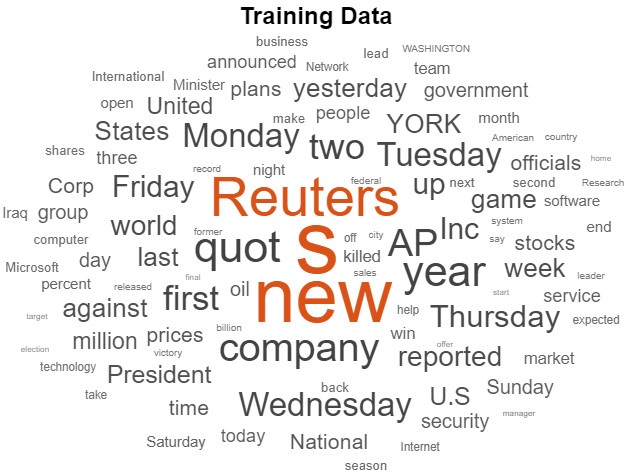


figure
histogram(data.Category);
xlabel("Class")
ylabel("Frequency")
title("Class Distribution")


cvp         = cvpartition(data.Category,'Holdout',0.2);
dataTrain   = data(training(cvp),:);
dataValidation = data(test(cvp),:);

textDataTrain = dataTrain.Var3;
textDataValidation = dataValidation.Var3;
YTrain      = dataTrain.Category;
YValidation = dataValidation.Category;

figure
wordcloud(textDataTrain);
title("Training Data")


documentsTrain      = preprocessText(textDataTrain);
documentsValidation = preprocessText(textDataValidation);

documentsTrain(1:5)

ans =   5×1 tokenizedDocument:

    12 tokens: reuters shortsellers wall streets dwindling band of ultracynics are seeing green again
    31 tokens: reuters soaring crude prices plus worries about the economy and the outlook for earnings are expected to hang over the stock market next week during the depth of the summer doldrums
    29 tokens: reuters authorities have halted oil export flows from the main pipeline in southern iraq after intelligence showed a rebel militia could strike infrastructure an oil official said on saturday
    23 tokens: afp tearaway world oil prices toppling records and straining wallets present a new economic menace barely three months before the us presidential elections
    34 tokens: reuters stocks ended slightly higher on friday but stayed near lows for the year as oil prices surged past 36 46 a barrel offsetting a positive outlook from computer maker dell inc dell o


## Encoding

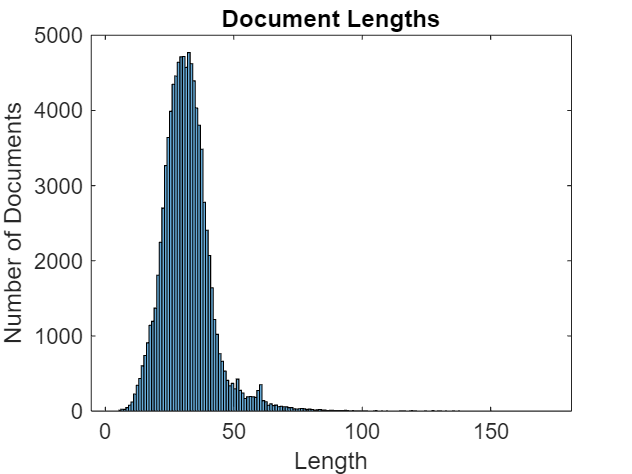

enc = wordEncoding(documentsTrain);

documentLengths = doclength(documentsTrain);
figure
histogram(documentLengths)
title("Document Lengths")
xlabel("Length")
ylabel("Number of Documents")


sequenceLength  = 10;
XTrain          = doc2sequence(enc,documentsTrain,'Length',sequenceLength);
XTrain(1:5)

ans = 5×1 cell array
    {[         1 2 3 4 5 6 7 8 9 10]}
    {[ 1 13 14 15 16 17 18 19 20 21]}
    {[ 1 41 42 43 44 45 46 30 47 25]}
    {[61 62 63 64 43 65 66 25 67 68]}
    {[ 1 80 81 82 83 37 84 85 86 87]}



XValidation     = doc2sequence(enc,documentsValidation,'Length',sequenceLength);


inputSize           = 1;
embeddingDimension  = 50;
numHiddenUnits      = 80;

numWords    = enc.NumWords;
numClasses  = numel(categories(YTrain));

layers = [ ...
    sequenceInputLayer(inputSize)
    wordEmbeddingLayer(embeddingDimension,numWords) % OPTIONAL
    lstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

layers =   6×1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 1 dimensions
     2   ''   Word Embedding Layer    Word embedding layer with 50 dimensions and 69954 unique words
     3   ''   LSTM                    LSTM with 80 hidden units
     4   ''   Fully Connected         4 fully connected layer
     5   ''   Softmax                 softmax
     6   ''   Classification Output   crossentropyex

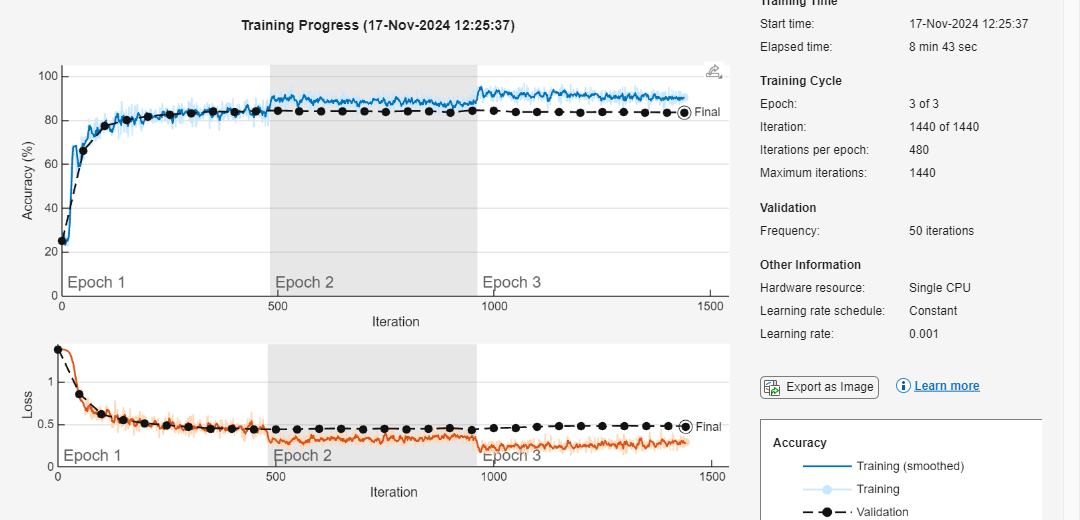


options = trainingOptions('adam', ...
    'MiniBatchSize', 200, ...
    'GradientThreshold',2, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{XValidation,YValidation}, ...
    'Plots','training-progress', ...
    'Verbose',false,...
    'MaxEpochs', 3);

net = trainNetwork(XTrain,YTrain,layers,options);

## New data: Today's news taken from Euronews

Remember 1: World News, 2: Sports, 3: Business, 4: Sci-Tech

todaysNews = [ ...
    "Britain’s King Charles leads national tribute to fallen soldiers."
    "European stocks saw a turbulent week as several companies missed earnings forecasts and US yields climbed."
    "Lionel Messi and Aitana Bonmati of Spain had been the favourites to win the 2023 trophies."];

documentsNew = preprocessText(todaysNews);

XNew = doc2sequence(enc,documentsNew,'Length',sequenceLength);

labelsNew = classify(net,XNew)

labelsNew = 3×1 categorical array
     1 
     3 
     2 


## Functions

function documents = preprocessText(textData)

% Tokenize the text.
documents = tokenizedDocument(textData);
% Convert to lowercase.
documents = lower(documents);
% Erase punctuation.
documents = erasePunctuation(documents);

end
